%% ====================================================================================================               

#   **Data-driven decision-making and Maintenance 4.0**

%======================================================================================================
%                                         ILIAS OUACHTOUK
%                                          1-2/04/2024
%======================================================================================================

# **TP1: Rolling Element Bearing Fault Diagnosis**

This "TP 1" will allow you to fault diagnosis of a rolling element bearing based on acceleration signals, especially in the presence of strong masking signals from other machine components. The "TP" will demonstrate how to apply envelope spectrum analysis to diagnose bearing faults and it is able to scale up to Big Data applications.

                                ** Fig1.**   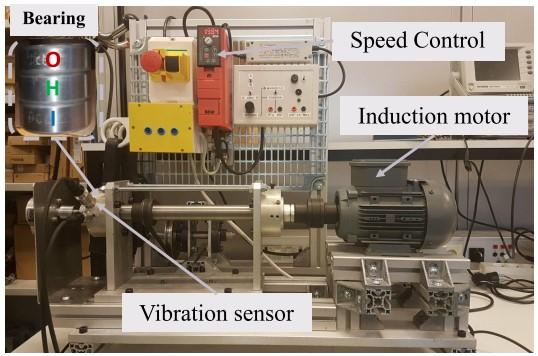

The test bench shown in Fig. 1 was developed at the LASPI (Laboratoire d’analyse des signaux et des processus industriels) laboratory in Universite Jean Monnet-Roanne. It consists of a shaft mounted on two bearings with rolling elements of type "RS-6205". The entire assembly is connected to an electric motor by means of a rigid coupling. The shaft speed is controlled by a variable speed drive. The asynchronous motor used in this experiment has these parameters: 0.25 kW, f=50 Hz and 2780 rpm.

This bench allows the measurement of the following signals: vibrations and currents. It is associated with a NI (National Instruments) acquisition card controlled by LabVIEW with a sampling frequency of fs =25600 Hz.

         ** Fig2.**    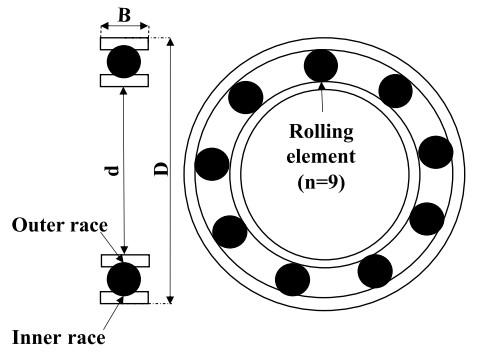         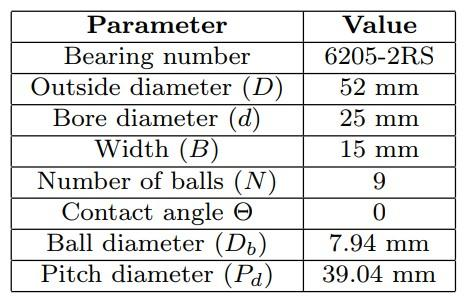

6205-2RS bearing with a pitch diameter of 39.04 mm has nine rolling elements. Each rolling element has a diameter of 7.94 mm. The angle of contact  is 0. An accelerometer samples the bearing vibrations at fs =25600 Hz.

% Vibration Analysis of Rolling Element Bearing Faults
load vib.mat
addpath('Functions');  
x=vib_h;
y=vib_o;
z=vib_i;
% Define the number of data points to be processed.
numSamples = length(x);
% Define sampling frequency.
fs = 25600         % unit: Hz

fs = 25600

%-----Define the parameters for the bearing-----
n = 9;         % Number of rolling element bearings
d = 7.94;      % Diameter of rolling elements 
pD = 39.04;      % Pitch diameter of bearing
thetaDeg = 0; % Contact angle in degrees
fr=33.33; %frequency by inveter

%--------------------Rolling Element Bearing Faults Frequency -----------------

Localized faults in a rolling element bearing may occur in the outer race, the inner race, the cage, or a rolling element. Each of these faults is characterized by its own frequency, which is usually listed by the manufacturer or calculated from the bearing specifications.

- Ballpass frequency, outer race (BPFO)

- Ballpass frequency, inner race (BPFI)

- Fundamental train frequency (FTF), also known as cage speed

- Ball (roller) spin frequency

As shown in the figure, *d* is the ball diameter, *D* is the pitch diameter. The variable   is the shaft speed, *n* is the number of rolling elements, *ϕ* is the bearing contact angle [1].

bpfi = ((n*fr)*(1+(d/pD)*cos(thetaDeg)))/2

bpfi = 180.4891

bpfo = ((n*fr)*(1-(d/pD)*cos(thetaDeg)))/2 

bpfo = 119.4809

**Plot the healthy and faulty Vibration data.**

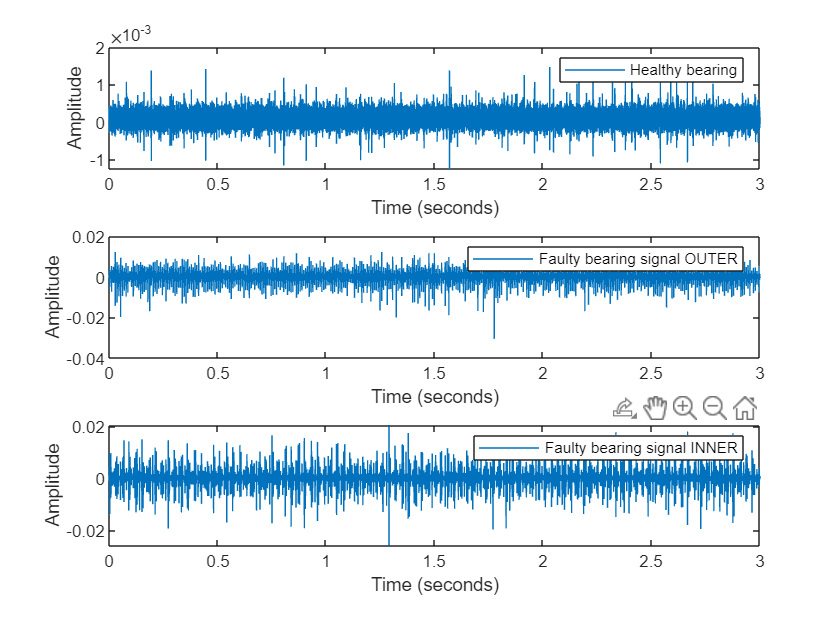

time = (0:numSamples-1)/fs;
figure(1)
% healthy bearing signal
subplot(3,1,1);
plot(time,vib_h); % plot the signal as a function of time;
xlabel('Time (seconds)'); % xlabel;
ylabel('Amplitude'); % ylabel;
legend('Healthy bearing'); % legend;

% faulty bearing signal OUTER
subplot(3,1,2);
plot(time,vib_o); % plot the signal as a function of time;
xlabel('Time (seconds)'); % xlabel;
ylabel('Amplitude'); % ylabel;
legend('Faulty bearing signal OUTER'); % legend;

% faulty bearing signal INNER
subplot(3,1,3);
plot(time,vib_i); % plot the signal as a function of time;
xlabel('Time (seconds)'); % xlabel;
ylabel('Amplitude'); % ylabel;
legend('Faulty bearing signal INNER'); % legend;

## Compare f**eatures**

In this section, representative features are extracted from each segment of data. These features will be used for health monitoring and prognostics. 

%%%%%%%%%%%%%%%%% time domaine indicator %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%




%------------------ Healthy signal ------------------------
vib_h_kurtosis=kurtosis(x)       %kurtosis 

vib_h_kurtosis = 5.3394


%------------------ faulty signal outer ------------------------
        vib_fo_kurtosis=kurtosis(y)     %kurtosis

vib_fo_kurtosis = 21.1464

%         vib_fo_rms=..........;              %rms
%------------------ faulty signal inner ------------------------        
        vib_fi_kurtosis=kurtosis(z)       %kurtosis

vib_fi_kurtosis = 19.3406

          %rms
% kurtosis/rms in healthy condition vs kurtosis in faulty condition

vib_h_rms=rms(x) %rms

vib_h_rms = 1.8277e-04

vib_fo_rms=rms(y)

vib_fo_rms = 0.0015

vib_fi_rms=rms(z)

vib_fi_rms = 0.0017

**Plot the healthy and faulty Vibration data.**

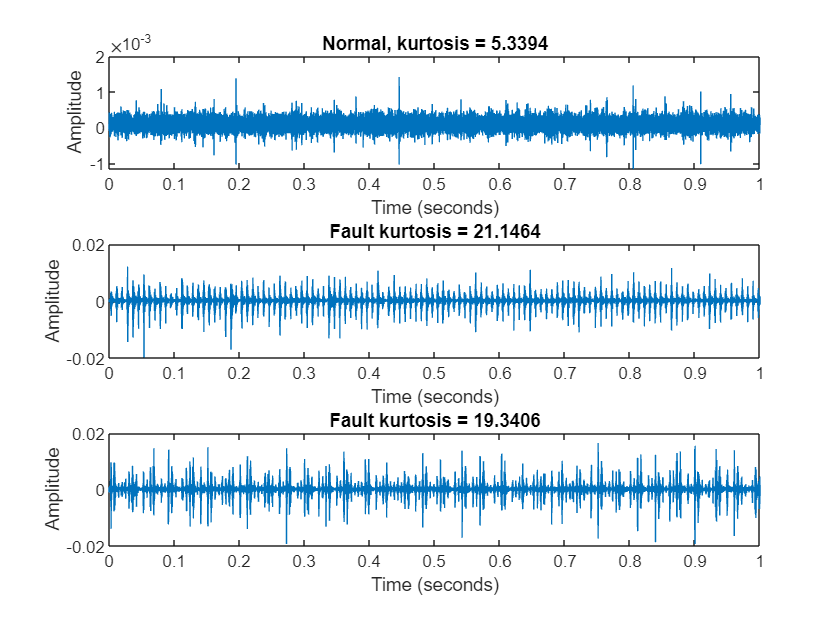

% figure
subplot(3, 1, 1)
plot(time,vib_h); % plot the signal as a function of time;
xlabel('Time (seconds)'); % xlabel;
ylabel('Amplitude'); % ylabel;
title(['Normal, kurtosis = ' num2str(vib_h_kurtosis)])
xlim([0 1])
% 
subplot(3, 1, 2)
plot(time,vib_o); % plot the signal as a function of time;
xlabel('Time (seconds)'); % xlabel;
ylabel('Amplitude'); % ylabel;
title(['Fault kurtosis = ' num2str(vib_fo_kurtosis) ])
xlim([0 1])
% 
subplot(3, 1, 3)
plot(time,vib_i); % plot the signal as a function of time;
xlabel('Time (seconds)'); % xlabel;
ylabel('Amplitude'); % ylabel;
title(['Fault kurtosis = ' num2str(vib_fi_kurtosis) ])
xlim([0 1])

# **Envelope Spectrum Analysis for Bearing Diagnosis**

When rolling elements hit the local faults at outer or inner races, or when faults on the rolling element hit the outer or inner races, the impact will modulate the corresponding critical frequencies, e.g. BPFO, BPFI, FTF, BSF. Therefore, the envelope signal produced by amplitude demodulation conveys more diagnostic information that is not available from spectrum analysis of the raw signal. 

### **Envelope spectrum for vibration machinery diagnosis (FFT).**

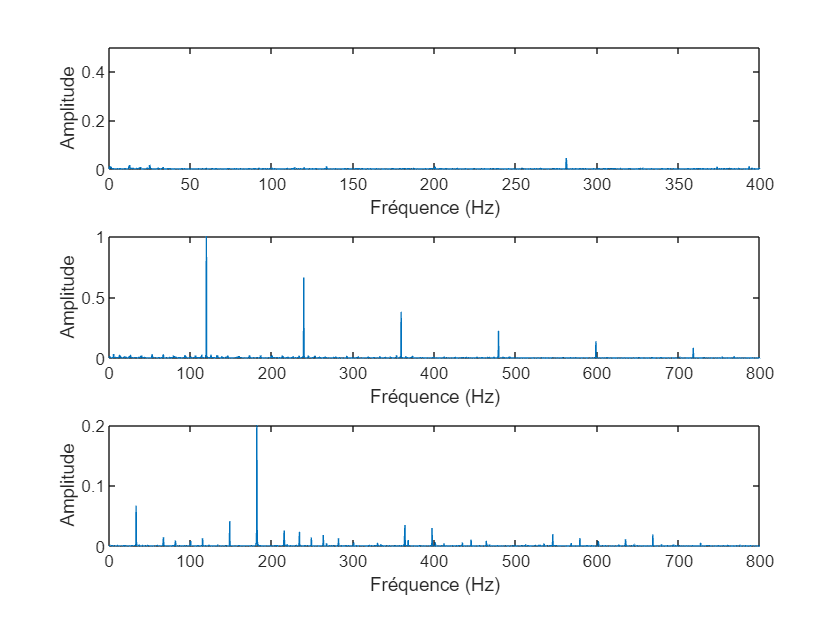

%------------------ Healthy signal ------------------------
figure
subplot(3, 1, 1)
plot_fft(x,fs); %This function calculates the Fast Fourier Transform (FFT) (Amplitude as a function of frequency)
xlabel('Fréquence (Hz)'); % xlabel;
ylabel('Amplitude'); % ylabel;
xlim([0 400])
ylim([0 0.5])
 %------------------ faulty signal outer ------------------------
subplot(3, 1, 2)
plot_fft(y,fs);
xlabel('Fréquence (Hz)'); % xlabel;
ylabel('Amplitude'); % ylabel;
xlim([0 800])
ylim([0 1])
 %------------------ faulty signal inner ------------------------
subplot(3, 1, 3)
plot_fft(z,fs);
xlabel('Fréquence (Hz)'); % xlabel;
ylabel('Amplitude');% ylabel;
xlim([0 800])
ylim([0 0.2])

### **Envelope spectrum for vibration machinery diagnosis (envspectrum).**

[Envelope Spectrum](https://fr.mathworks.com/help/signal/ref/envspectrum.html)** of Vibration Signals: **Simulate two vibration signals, one from a healthy bearing and one from a damaged bearing. Compute and compare their envelope spectra.

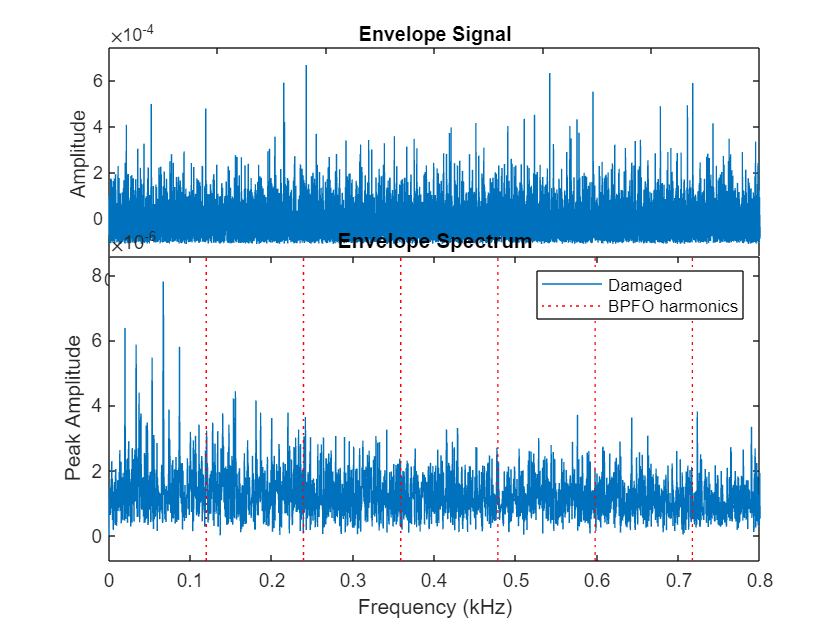

 %------------------ Healthy signal ------------------------
envspectrum(x,fs) ; % returns the envelope spectrum of a signal x sampled at a rate fs. 
xlim([0 800]/1000)
harmImpactO = (1:20)*bpfo;
harmImpactI = (1:20)*bpfi;
[X,Y] = meshgrid(harmImpactO,ylim);
hold on
plot(X/1000,Y,':r')
legend('Damaged','BPFO harmonics')
hold off

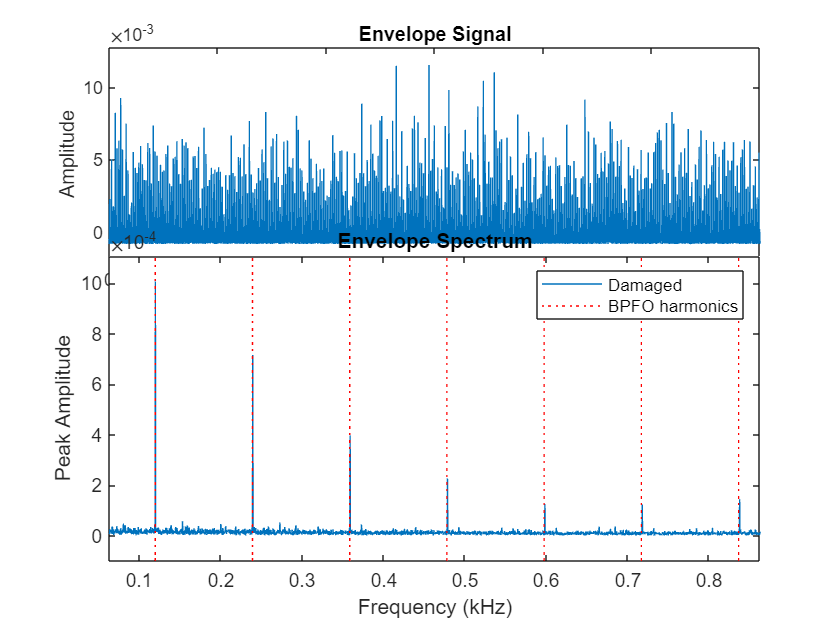


%------------------ outer faulty signal ------------------------
envspectrum(y,fs) ; % returns the envelope spectrum of a signal x sampled at a rate fs. 
xlim([0 800]/1000)
harmImpactO = (1:20)*bpfo;
harmImpactI = (1:20)*bpfi;
[X,Y] = meshgrid(harmImpactO,ylim);
hold on
plot(X/1000,Y,':r')
legend('Damaged','BPFO harmonics')
hold off

D'après le plot, on voit bien que les Harmoniques de la BPFO match bien le signal Damaged, car dans ce cas on a le défaut outer. Ca correspond bien à nos attentes. 

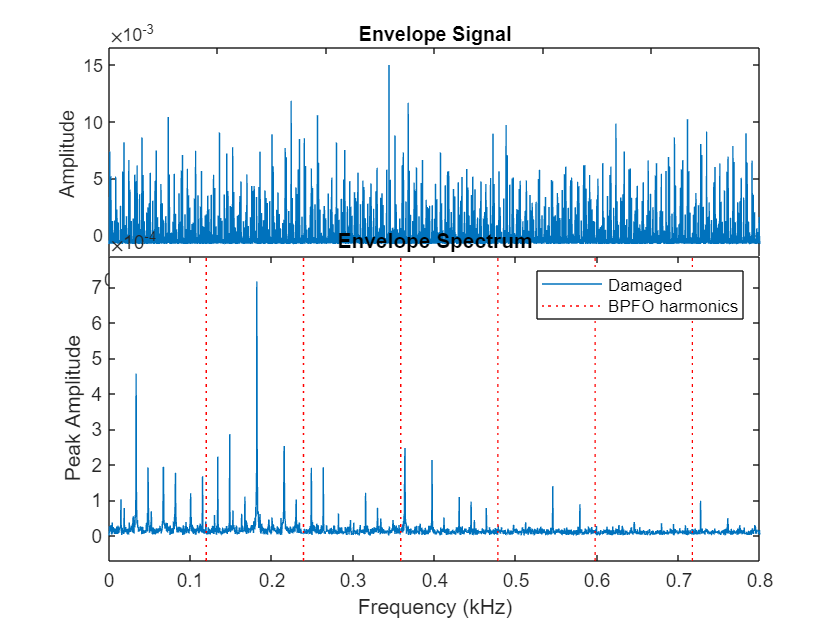

 

 %------------------ inner faulty signal ------------------------


 envspectrum(z,fs) ; % returns the envelope spectrum of a signal x sampled at a rate fs. 
xlim([0 800]/1000)
harmImpactO = (1:20)*bpfo;
harmImpactI = (1:20)*bpfi;
[X,Y] = meshgrid(harmImpactO,ylim);
hold on
plot(X/1000,Y,':r')
legend('Damaged','BPFO harmonics')
hold off

 %------------------ Healthy signal ------------------------
envspectrum(x,fs) ; % returns the envelope spectrum of a signal x sampled at a rate fs. 
xlim([0 800]/1000)
harmImpactO = (1:20)*bpfo;
harmImpactI = (1:20)*bpfi;

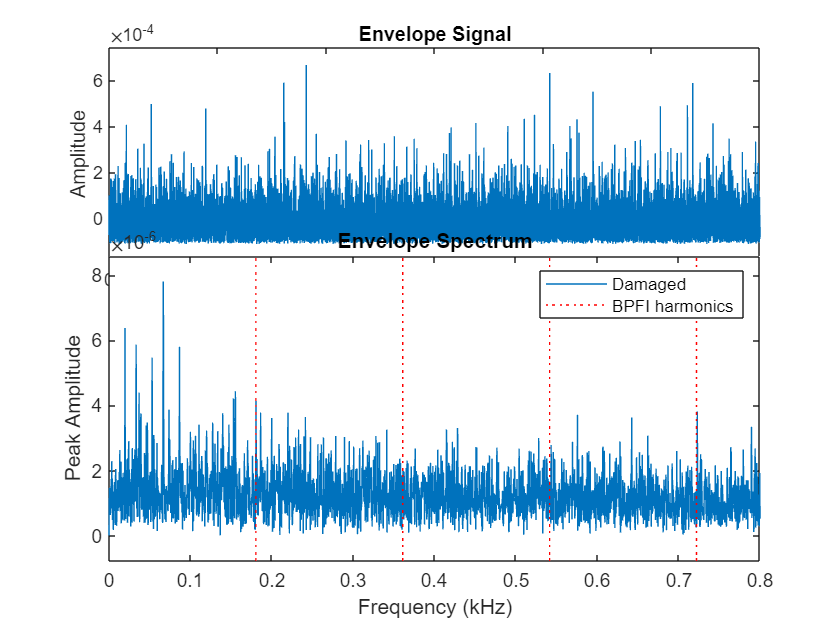

[X,Y] = meshgrid(harmImpactI,ylim);
hold on
plot(X/1000,Y,':r')
legend('Damaged','BPFI harmonics')
hold off

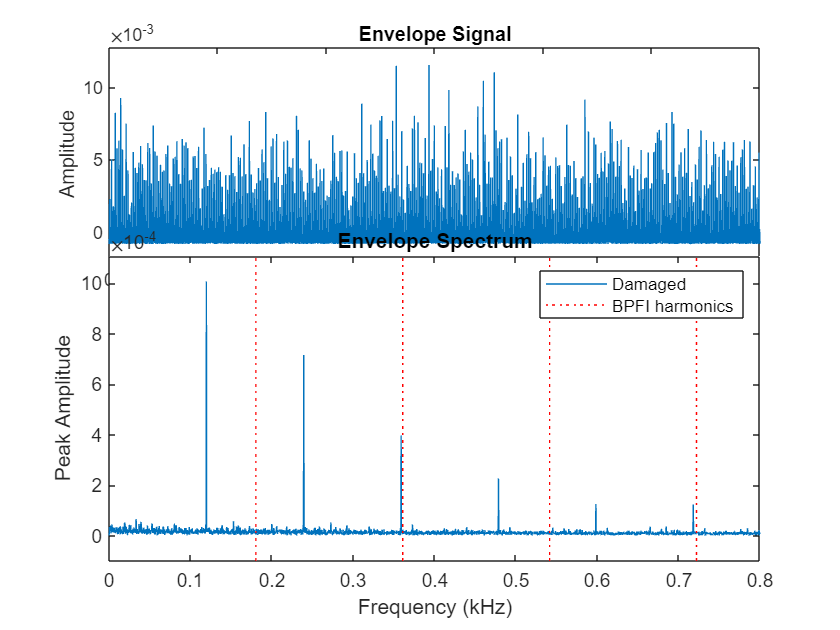

%------------------ outer faulty signal ------------------------
envspectrum(y,fs) ; % returns the envelope spectrum of a signal x sampled at a rate fs. 
xlim([0 800]/1000)
harmImpactO = (1:20)*bpfo;
harmImpactI = (1:20)*bpfi;
[X,Y] = meshgrid(harmImpactI,ylim);
hold on
plot(X/1000,Y,':r')
legend('Damaged','BPFI harmonics')
hold off

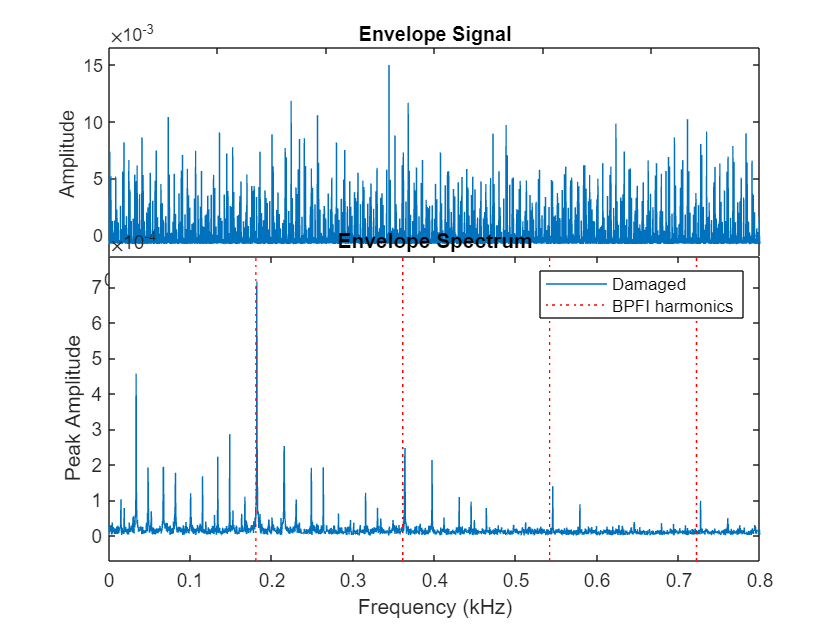


%------------------ inner faulty signal ------------------------


 envspectrum(z,fs) ; % returns the envelope spectrum of a signal x sampled at a rate fs. 
xlim([0 800]/1000)
harmImpactO = (1:20)*bpfo;
harmImpactI = (1:20)*bpfi;
[X,Y] = meshgrid(harmImpactI,ylim);
hold on
plot(X/1000,Y,':r')
legend('Damaged','BPFI harmonics')
hold off

D'après le plot, on voit bien que les Harmoniques de la BPFI match bien le signal Damaged, car dans ce cas on a le défaut inner. Ca correspond bien à nos attentes.